# EPFL ENV-424 - Water Ressource Engineering Project - Autumn 2022 - Group D

# Plan of a multipurpose reservoir

A reservoir is used for hydroelectrical energy production and flood prevention. You should evaluate the feasibility of improving the flood control operations of an existing reservoir of a hydropower plant. A larger fraction of the storage needs to be reserved for flood control and cannot be used for hydroelectric generation. The downstream part of the river should be protected from floods larger than Q lim . The larger the volume for hydroelectric use, the higher the energy production. The larger the volume for flood control, the more efficiently floods can be attenuated. The two uses (hydroelectric and flood control) are therefore in competition. The goal of the assignment is to estimate the trade off between money earned with energy production and probability that the released flow Q out exceeds Q lim , as a function of the volume reserved for flood control. Note that the discharge used for hydropower generation is then released into a different river system.

`All deliverables can be easily found as they are introduced in this specific font.`

## **Read all input parameters (P, Q, etc.) **

load data/P.txt
load data/Q_obs.txt
load data/temperature.txt
load data/kc.txt
load data/area_rating_curve.txt %[elevation above sea level, lake area]

## **Setting the parameters **

%hydrological model
sw=0.25;     %wilting point
s1=0.4;      %soil moisture stress threshold
n=0.3;       %porosity
Qb=7;        %m^3/s, baseflow
tsup=22;     %h, mean superficial residence time
A=4000;      %km^2, catchment area
phi=38;       %degree, latitude% 
n_years=6;  

%ARBITRARY VALUES
Ksat=5*10^-6;         %saturated hydraulic conductivity, K(s)=Ksat*s^c [m/s]
c=7;          
tsub=10*24;        %h, mean sub-superficial residence time
z=1;          %m, root zone thickness

dt=1;
doTest=1;

## **Calibration of the hydrological model**

[Ksat, c, tsub, z, NS] = GroupD_f_calibration(Q_obs, phi, temperature, n_years, P, sw, s1, kc, n, Qb, tsup, A, dt, tsub, c, Ksat, z, doTest)

testS = 0.0879

testQ = 0.0814

Q = 	1.0e+03 *

    0.0070    0.0077    0.0076    0.0076    0.0910    0.0906    0.0903    0.0899    0.1727    0.1720    0.1713    0.2322    0.2313    0.2303    0.2299    0.2290    0.2282    0.2273    0.2682    0.2671    0.3493    0.3479    0.3827    0.3812    0.3796    0.3782    0.3767    0.3751    0.3736    0.3721    0.3706    0.3691    0.3676    0.3661    0.3646    0.3631    0.3616    0.3601    0.3587    0.3572    0.3557    0.3543    0.3528    0.3514    0.3500    0.3485    0.3471    0.3457    0.3443    0.3429


R =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


I =     0.0126
    0.0236
    0.4770
    0.1694
    0.0250
    0.0641
    0.2154
    0.2057
    0.0079
    0.2794


s =     0.5000
    0.0631
    0.1418
    1.0000
         0
    0.0833
    0.2970
    0.9996
         0
    0.0263


L =     0.1406
    0.0000
    0.0000
   18.0000
         0
    0.0000
    0.0037
   17.9479
         0
    0.0000


ET =     0.0030
         0
         0
    0.0030
         0
         0
    0.0010
    0.0030
         0
         0


testS = 1.0009

testQ = 1.0015

Ksat = 4.5774e-06

c = 7.4409

tsub = 218.0680

z = 106.9767

NS = 0.5798

`1. Best parameters for the hydrological model: `

`Ksat = `

`c = `

`z = `

`tsub = `

## **Run the hydrological model **

[Q, R, I, s, L, ET] = GroupD_f_hydromodel(phi,temperature,n_years,P,Ksat,sw,s1,kc,n,Qb,tsup,tsub,A,c,dt,z,doTest)

testS = 1.0009

testQ = 1.0015

Q =     7.0000    7.4832    7.9455    8.3905    8.9213    9.4648    9.9845   10.4914   11.0228   11.5760   12.0995   12.6641   13.2201   13.7493   14.2785   14.7953   15.2854   15.7540   16.2393   16.7122   17.2341   17.8168   18.4373   19.0239   19.5897   20.1334   20.6425   21.1203   21.5695   21.9926   22.3917   22.7688   23.1253   23.4629   23.7829   24.0865   24.3748   24.6487   24.9092   25.1570   25.3929   25.6176   25.8317   26.0357   26.2303   26.4159   26.5930   26.7620   26.9232   27.0771


R =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


I =     0.0126
    0.0236
    0.4770
    0.1694
    0.0250
    0.0641
    0.2154
    0.2057
    0.0079
    0.2794


s =     0.5000
    0.4973
    0.4951
    0.5072
    0.5091
    0.5064
    0.5050
    0.5085
    0.5114
    0.5081


L =     0.0948
    0.0912
    0.0882
    0.1054
    0.1084
    0.1042
    0.1022
    0.1074
    0.1122
    0.1069


ET =     0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030


`2. Plot the time series (6-year-long) of precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the given precipitation).`

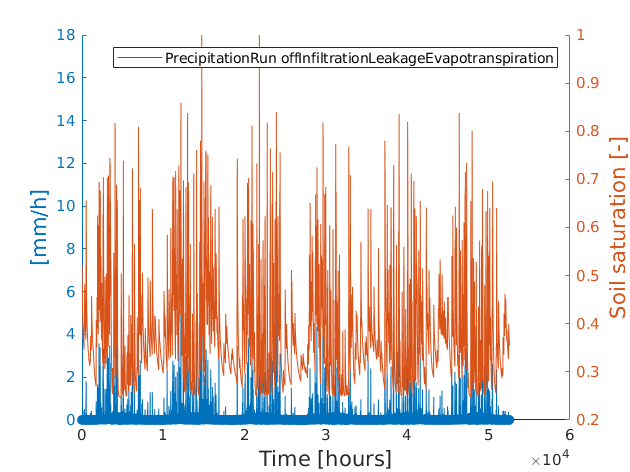

figure  
yyaxis left 
plot(P);
hold on 
plot(R);   
plot(I);
plot(L);
plot(ET);
ylabel('[mm/h]','fontsize',14) 

yyaxis right 
plot(s);
ylabel('Soil saturation [-]','fontsize',14) 

legend(['Precipitation', 'Run off', 'Infiltration', 'Leakage', 'Evapotranspiration'])
xlabel('Time [hours]','fontsize',14)
box off

## **Discharge generation **

Nyears_gen = 100;               %[years]
max_Kc = Ksat(NS==max(NS));     %[m/s]  hydraulic conductivity (saturated soil) for the maximum Nash-Sutcliffe index NS
max_z = z(NS==max(NS));         %[mm]   root zone depth for the maximum Nash-Sutcliffe index NS
max_c = c(NS==max(NS));         %[-]    exponent for power-law relation for the maximum Nash-Sutcliffe index NS
max_tsub = tsub(NS==max(NS));   %[h]    mean sub-superficial residence time for the maximum Nash-Sutcliffe index NS

[time_gen,Q_gen,R_gen,I_gen,soil_saturation_gen,L_gen,ET_gen,P_gen_mean_monthly] = GroupD_f_discharge(Nyears_gen, P, temperature, kc, dt, n, max_z,max_Kc,sw,s1,max_c,tsup,max_tsub,A,Qb,phi,doTest);

Pgen_hourly =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


testS = 1.0004

testQ = 1.0006

Q_gen_daily =    24.0193
   24.1783
   24.1261
   24.4061
   24.7162
   25.1431
   26.9329
   28.5166
   29.0670
   29.3503


`3. Plot the time series of observed discharge and of the discharge as simulated by the hydrological model with the best fit parameters`

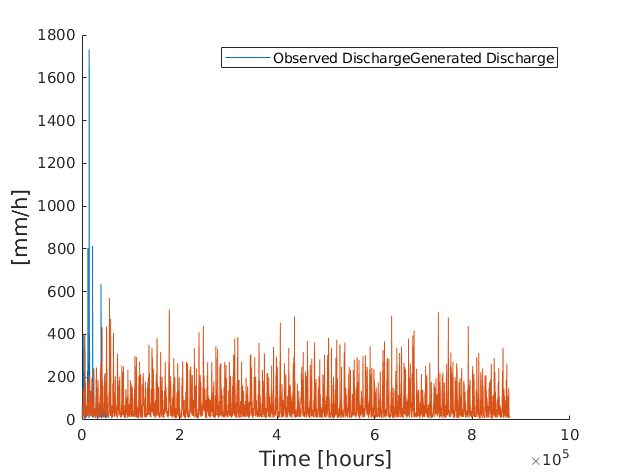

figure  
plot(Q_obs);
hold on 
plot(Q_gen);   
legend(['Observed Discharge', 'Generated Discharge'])
ylabel('[mm/h]','fontsize',14) 
xlabel('Time [hours]','fontsize',14)
box off

`4. Plot Markov chains of the calibrated parameters and sequences of values of N S and T SA as a function of the number of iterations. Only plot accepted parameter sets.`

`5. Plot the comparison between the statistics (mean, standard deviation, α and λ) of the observed and generated precipitation.`

`6. Plot the time series (100-year-long) of generated precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the generated precipitation).`

figure 
Q_gen,R_gen,I_gen,soil_saturation_gen,L_gen,ET_gen,P_gen_mean_monthly

Q_gen =     7.0000    7.4832    7.9428    8.3804    8.7977    9.1961    9.5771    9.9416   10.2908   10.6256   10.9469   11.2555   11.5521   11.8374   12.1120   12.3764   12.6312   12.8769   13.1138   13.3425   13.5633   13.7766   13.9826   14.1818   14.3744   14.5607   14.7411   14.9156   15.0847   15.2487   15.4076   15.5616   15.7110   15.8558   15.9964   16.1328   16.2650   16.3935   16.5182   16.6392   16.7567   16.8707   16.9814   17.0887   17.1929   17.2942   17.3926   17.4881   17.5809   17.6711


R_gen =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


I_gen =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


soil_saturation_gen =     0.5000
    0.4969
    0.4940
    0.4912
    0.4885
    0.4860
    0.4835
    0.4811
    0.4788
    0.4765


L_gen =     0.0948
    0.0906
    0.0867
    0.0831
    0.0798
    0.0767
    0.0739
    0.0712
    0.0687
    0.0663


ET_gen =     0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030
    0.0030


P_gen_mean_monthly =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


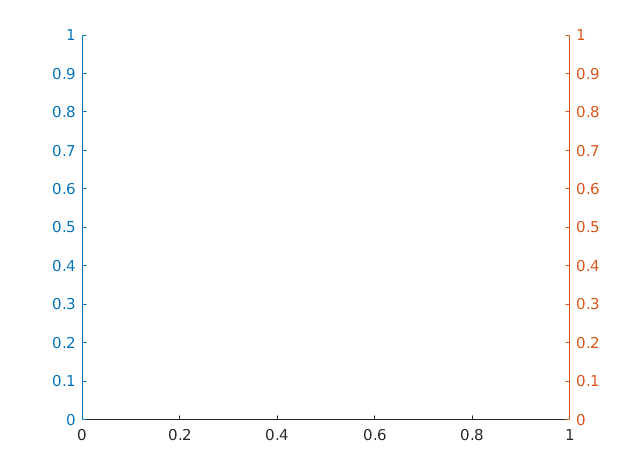

yyaxis left

plot(P_gen_monthly);

Unrecognized function or variable 'P_gen_monthly'.

hold on 
plot(R_gen);   
plot(I_gen);
plot(L_gen);
plot(ET_gen);
ylabel('[mm/h]','fontsize',14) 

yyaxis right 
plot(soil_saturation_gen);
ylabel('Soil saturation [-]','fontsize',14) 

legend(['Precipitation', 'Run off', 'Infiltration', 'Leakage', 'Evapotranspiration'])
xlabel('Time [hours]','fontsize',14)
box off

`7. Plot the area and the volume rating curves for the given levels.`

`8. Report the minimum flow (discharge that is equalled or exceeded 95% of the time) of the generated discharge and plot the discharge duration curves.`

figure                                             
plot(time_gen,Q_gen);                 
ylabel('Generated hourly discharge  [m^{3}/s]','fontsize',14) 
xlabel('Time [hours]','fontsize',14)
box off

figure
plot(1:365,Q_gen_daily)
ylabel('Mean daily discharge [m^3/s]','fontsize',14)
xlabel('Days','fontsize',14)
box off

figure
plot(1:12,Q_gen_mean_monthly)
ylabel('Mean monthly discharge [m^3/s]','fontsize',14)
xlabel('Months','fontsize',14)
box off

`9. For a maximum level for hydroelectric use of 15 m, plot the time series (100 years long) of input discharge, output discharge, volume within the reservoir and level.`

`10. Plot the average annual energy production in [GWh] and the probability that Q out exceeds Q lim for different values of the maximum level for hydroelectrical use.`

`11. Plot the Pareto front of average annual energy production in [GWh] vs the probability that Q out exceeds Q lim computed from different values of the maximum level for hydroelectrical use.`